% === Configuração do ROS ===
clc; clear all; close all;
setenv('ROS_MASTER_URI','http://192.168.245.132:11311');
setenv('ROS_IP','192.168.245.1');
rosshutdown;

Shutting down global node /matlab_global_node_05558 with NodeURI http://192.168.245.1:54530/ and MasterURI http://192.168.245.132:11311.


rosinit('192.168.245.132', 11311);

The value of the ROS_IP environment variable, 192.168.245.1, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_60415 with NodeURI http://192.168.245.1:49918/ and MasterURI http://192.168.245.132:11311.


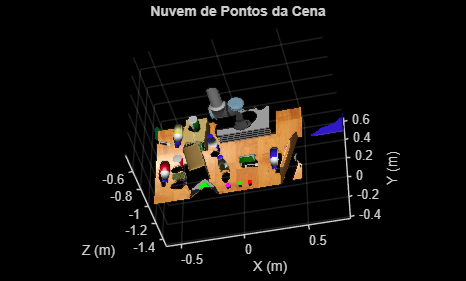

% === Captura da nuvem de pontos do sensor ===
pcSub = rossubscriber('/camera/depth/points', 'sensor_msgs/PointCloud2', 'DataFormat', 'struct');
pause(1);
pcMsg = receive(pcSub, 3);

% Extrai XYZ
xyz = rosReadXYZ(pcMsg, "PreserveStructureOnRead", true);
xyzVec = reshape(xyz, [], 3);

% Extrai RGB (opcional)
try
    rgb = rosReadRGB(pcMsg, "PreserveStructureOnRead", true);
    rgbVec = reshape(rgb, [], 3);
    hasColor = true;
catch
    hasColor = false;
end

% Remove NaNs
valid = ~any(isnan(xyzVec), 2);
xyzClean = xyzVec(valid, :);
xyzClean(:,3) = -xyzClean(:,3);  % Inverte o eixo Z para alinhar com câmera

% Cria ptCloud da cena
if hasColor
    rgbClean = uint8(255 * rgbVec(valid, :));
    ptCena_1 = pointCloud(xyzClean, "Color", rgbClean);
else
    ptCena_1 = pointCloud(xyzClean);
end

% Mostrar cena
figure;
pcshow(ptCena_1, VerticalAxis="Y", VerticalAxisDir="Up");
title("Nuvem de Pontos da Cena");
xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");

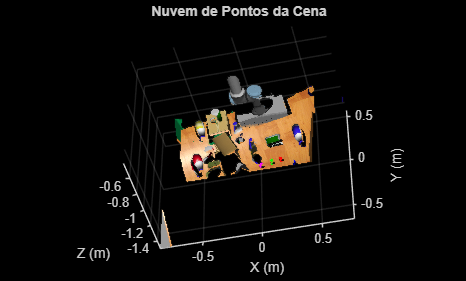

% === Captura da nuvem de pontos do sensor ===
pcSub = rossubscriber('/camera/depth/points', 'sensor_msgs/PointCloud2', 'DataFormat', 'struct');
pause(1);
pcMsg = receive(pcSub, 3);

% Extrai XYZ
xyz = rosReadXYZ(pcMsg, "PreserveStructureOnRead", true);
xyzVec = reshape(xyz, [], 3);

% Extrai RGB (opcional)
try
    rgb = rosReadRGB(pcMsg, "PreserveStructureOnRead", true);
    rgbVec = reshape(rgb, [], 3);
    hasColor = true;
catch
    hasColor = false;
end

% Remove NaNs
valid = ~any(isnan(xyzVec), 2);
xyzClean = xyzVec(valid, :);
xyzClean(:,3) = -xyzClean(:,3);  % Inverte o eixo Z para alinhar com câmera

% Cria ptCloud da cena
if hasColor
    rgbClean = uint8(255 * rgbVec(valid, :));
    ptCena_2 = pointCloud(xyzClean, "Color", rgbClean);
else
    ptCena_2 = pointCloud(xyzClean);
end

% Mostrar cena
figure;
pcshow(ptCena_2, VerticalAxis="Y", VerticalAxisDir="Up");
title("Nuvem de Pontos da Cena");
xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");

gridStep = 0.05;   % apenas para alinhamento
mergeStep = 0.005; % para fusão de alta densidade (ex: 5mm)

% Etapa 1: downsample e denoise só para registrar
pt1_ds = pcdenoise(pcdownsample(ptCena_1, "gridAverage", gridStep));
pt2_ds = pcdenoise(pcdownsample(ptCena_2, "gridAverage", gridStep));

% Etapa 2: registra a nuvem 2 sobre a 1
[tform, ~, rmse] = pcregistericp(pt2_ds, pt1_ds, ...
    Metric="planeToPlane", InitialTransform=rigidtform3d);
disp("RMSE do ICP: " + rmse);

RMSE do ICP: 0.10386


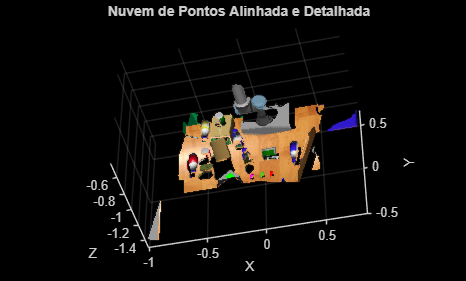


% Etapa 3: aplica transformação à nuvem original (completa)
pt2_aligned = pctransform(ptCena_2, tform);

% Etapa 4: fusão de nuvens completas (com densidade preservada)
ptFinal = pcmerge(ptCena_1, pt2_aligned, mergeStep);

% Visualização
figure;
pcshow(ptFinal, VerticalAxis="Y", VerticalAxisDir="Up");
title("Nuvem de Pontos Alinhada e Detalhada");
xlabel("X"); ylabel("Y"); zlabel("Z");

% ==Importar modelo superfície sem a parte de baixo==
meshData = stlread("C:\Users\pecci\OneDrive\Desktop\Modelos_garra\bottle.stl");

% Detectar o tipo de retorno
if isa(meshData, "triangulation")
    tri = meshData;

elseif isstruct(meshData) && all(isfield(meshData, ["Points", "ConnectivityList"]))
    tri = triangulation(meshData.ConnectivityList, meshData.Points);

elseif iscell(meshData)
    [faces, vertices] = meshData{:};
    tri = triangulation(faces, vertices);

else
    error("Formato de saída de stlread não reconhecido.");
end

% ==Gerar nuvem de pontos==
ptModelo = mesh2pc(tri, ...
    NumPoints=5000, ...
    SamplingMethod="PoissonDiskSampling");

% ==Aplicar correção de escala==
scaleFactor = 0.034; % Fator de escala
locationsScaled = ptModelo.Location * scaleFactor;

% ==Remover pontos com z < 0==
idx_valid = locationsScaled(:,3) >= 0;
locationsFiltered = locationsScaled(idx_valid, :);

% Criar nova nuvem com pontos válidos
ptCloudScaled = pointCloud(locationsFiltered);

% Se existirem normais, manter apenas as correspondentes
if ~isempty(ptModelo.Normal)
    ptCloudScaled.Normal = ptModelo.Normal(idx_valid, :);
end

% % ==Visualização==
% figure('Name','Nuvem de Pontos da Malha STL','Color','w');
% pcshow(ptCloudScaled, 'MarkerSize', 30);
% title('Nuvem de Pontos do Modelo STL (Z >= 0)');
% xlabel('X'); ylabel('Y'); zlabel('Z');
% axis equal; grid on;
% view(3);

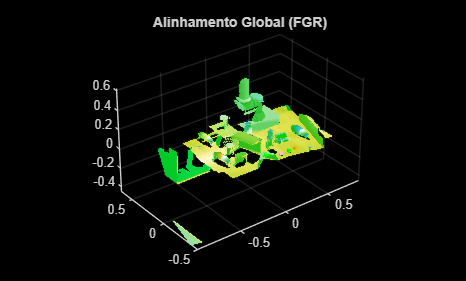

%== FGR ==

%simplifica a nuvem e tira ruido
grid = 0.001;
mdl_ds = pcdownsample(ptFinal, 'gridAverage', grid);
scn_ds = pcdownsample(ptCloudScaled, 'gridAverage', grid);

% Execute o FGR
tformGlobal = pcregisterfgr(mdl_ds, scn_ds, grid, MaxIterations=100);

% Visualize o alinhamento global
ptModelGlobal = pctransform(ptFinal, tformGlobal); % Cria modelo alinhado com o detectado
figure;
pcshowpair(ptCloudScaled, ptModelGlobal);
title('Alinhamento Global (FGR)');